params.gridSize = 5;
params.initialIntensity = 1;
params.ignitionCells = [3 3];
params.spreadRate = 0.1;
params.decayRate = 0.01;

params.numDrones = 1;

fire = init_fire(params);
drones = init_drones(params);

disp("Initial Fire:")

Initial Fire:


fire.intensity

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     1     0     0
     0     0     0     0     0
     0     0     0     0     0



disp("Initial Drone Position:")

Initial Drone Position:


drones(1).position

ans =      2     4



[drones, fire] = drone_step(drones, fire, params);

Drone pos:
     2     3

Target:
     3     3




disp("After One Step:")

After One Step:


fire.intensity

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     1     0     0
     0     0     0     0     0
     0     0     0     0     0


drones(1)

ans = struct with fields:
                   id: 1
             position: [2 3]
               target: [3 3]
           waterLevel: 1
     distanceTraveled: 1
    extinguishedCells: 0
                  log: [2×2 double]



%Movement Test Ninja?!?! ( I really hope you understand what I mean lol)

params.gridSize = 5;
params.numDrones = 1;

fire.intensity = zeros(5);
fire.intensity(5,5) = 1; % target in corner

drones(1).id = 1;
drones(1).position = [1 1];
drones(1).target = [0 0];
drones(1).distanceTraveled = 0;
drones(1).extinguishedCells = 0;
drones(1).log = [];

[drones, fire] = drone_step(drones, fire, params);

Drone pos:
     1     2

Target:
     5     5




drones(1).position

ans =      1     2



%Targeting Test

fire.intensity = zeros(5);
fire.intensity(5,5) = 1;

drone.position = [1 1];

target = find_target(drone, fire)

target =      5     5



%Extinguishing Test

fire.intensity = zeros(5);
fire.intensity(3,3) = 1;

drone.position = [3 3];
drone.extinguishedCells = 0;

[drone, fire] = drop_water(drone, fire);

fire.intensity

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


drone.extinguishedCells

ans = 1


%Collision Test
params.gridSize = 5;

drones(1).id = 1;
drones(1).position = [2 2];
drones(1).target = [3 2];

drones(2).id = 2;
drones(2).position = [3 2];

newPos = move_drone(drones(1), drones, params)

newPos =      2     2



%Together
params.gridSize = 7;
params.initialIntensity = 1;
params.ignitionCells = [4 4];
params.spreadRate = 0.05;
params.decayRate = 0.04;
params.numDrones = 15; %I didnt wanna mess with Judy's preset decay and spread so i increased my fleet. Dont go over 12-13 cause then the fire just gone asap

fire = init_fire(params);
drones = init_drones(params);

for t = 1:20
    fire = fire_step(fire, params);
    [drones, fire] = drone_step(drones, fire, params);

    fprintf("Step %d | max fire = %.3f\n", t, max(fire.intensity(:)));
end

Drone pos:
     2     2

Target:
     4     3

Drone pos:
     1     6

Target:
     3     4

Drone pos:
     6     1

Target:
     4     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     5

Target:
     3     4

Drone pos:
     7     5

Target:
     5     4

Drone pos:
     3     6

Target:
     3     4

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     7     3

Target:
     5     4

Drone pos:
     2     6

Target:
     4     4

Drone pos:
     2     3

Target:
     4     4

Drone pos:
     5     3

Target:
     5     4

Drone pos:
     5     5

Target:
     5     4



Step 1 | max fire = 0.960


Drone pos:
     3     2

Target:
     4     3

Drone pos:
     1     5

Target:
     3     4

Drone pos:
     6     2

Target:
     5     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     6     4

Drone pos:
     3     6

Target:
     3     4

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     5     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 2 | max fire = 0.970


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     3     6

Target:
     3     4

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 3 | max fire = 0.980


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     3     6

Target:
     3     4

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 4 | max fire = 0.990


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     3     6

Target:
     3     4

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 5 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 6 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 7 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     5

Target:
     4     4

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 8 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     4

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     3     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 9 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 10 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     4

Target:
     3     4

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 11 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 12 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 13 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 14 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 15 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 16 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 17 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 18 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 19 | max fire = 1.000


Drone pos:
     4     2

Target:
     4     3

Drone pos:
     1     5

Target:
     1     5

Drone pos:
     6     2

Target:
     6     3

Drone pos:
     4     5

Target:
     4     5

Drone pos:
     3     5

Target:
     3     5

Drone pos:
     4     3

Target:
     4     3

Drone pos:
     2     4

Target:
     3     4

Drone pos:
     7     4

Target:
     7     4

Drone pos:
     4     6

Target:
     4     6

Drone pos:
     3     4

Target:
     3     4

Drone pos:
     6     3

Target:
     6     3

Drone pos:
     2     6

Target:
     2     6

Drone pos:
     3     3

Target:
     5     3

Drone pos:
     5     3

Target:
     5     3

Drone pos:
     5     5

Target:
     5     5



Step 20 | max fire = 1.000


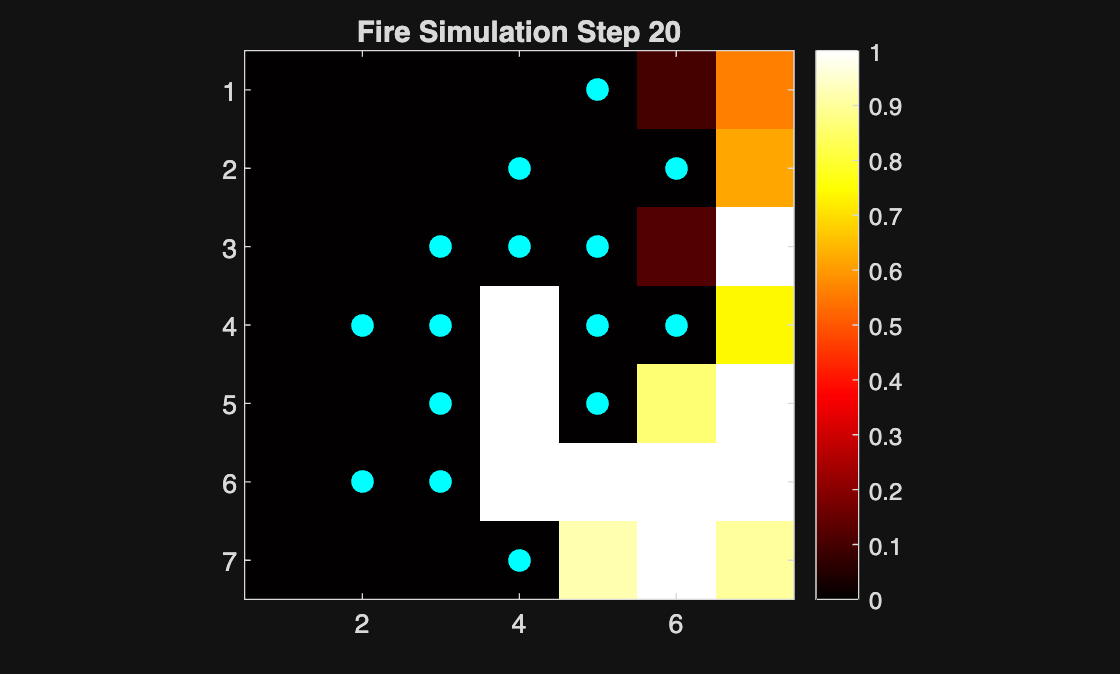

%Heatmap DELETE TS cause its straight chat
figure(1)
clf

imagesc(fire.intensity)
colormap hot
colorbar
caxis([0 1])
axis equal tight

hold on

% overlay drones
for i = 1:length(drones)
    pos = drones(i).position;

    plot(pos(2), pos(1), 'co', ...
        'MarkerSize', 8, ...
        'MarkerFaceColor', 'c')
end

title(sprintf('Fire Simulation Step %d', t))

drawnow
hold off